close all;
clear;
clc;


%SNR in db
Eb_Nodb = 1:1:10 ;
Eb_No = 10 .^ (Eb_Nodb/10);
n = 3 ;
k = 1 ;
R = k/n ;
num_samples = 10000;


%uncoded
BER_uncoded = zeros(1,length(Eb_No));

for i= 1 : 10
    sigma_uncoded = sqrt(1/(2*Eb_No(i)));
    %initialization
    uncoded_num_errors = 0;
    uncoded_msg=0;
    uncoded_mod_out =0;
    uncoded_channel_out = 0;
    uncoded_demod_out = 0;
    for j = 1:num_samples
        uncoded_msg = randi([0,1]);
        %modulation
        if(uncoded_msg == 0)
            uncoded_mod_out = -1;
        else
            uncoded_mod_out = 1;
        end
    %noise
    uncoded_channel_out = uncoded_mod_out + sigma_uncoded*(randn(1,1));
    %decision decoding
    uncoded_demod_out = uncoded_channel_out > 0 ;
    uncoded_num_errors = uncoded_num_errors + abs(uncoded_demod_out - uncoded_msg);
    end
BER_uncoded(i) = uncoded_num_errors/num_samples;
end



%repetition channel coding
BER_hardcode = zeros(1,length(Eb_No));
BER_softcode = zeros(1,length(Eb_No));

for i= 1 : length(Eb_No)
    sigma_coded = sqrt(1/(2*R*Eb_No(i)));
    %initialization
    hard_num_errors = 0;
    hard_decod_out = zeros(1,n);
    hard_demod_out = zeros(1,n);
    soft_decod_out = 0;
    soft_num_errors = 0;
    dmin1=0;
    dmin2=0;
    for j = 1:num_samples
        msg = randi([0,1]);
        %encoding
        msg_encoded = [msg msg msg];
        %modulation
        if(msg_encoded == [0 0 0])
            mod_out = [-1 -1 -1];
        else
            mod_out = [1 1 1];
        end
        %noise
    channel_out = mod_out + sigma_coded*(randn(1,n));
    %hard decision decoding
    hard_demod_out = channel_out > 0 ;
    hard_decod_out = sum(hard_demod_out)>=2;
    hard_num_errors = hard_num_errors + abs(hard_decod_out - msg);
    % soft decision decoding
    dmin1 = sum((channel_out-[1 1 1]).^2);
    dmin2 = sum((channel_out-[-1 -1 -1]).^2);
        if(dmin2>=dmin1)
            soft_decod_out = 1;
        else
            soft_decod_out = 0;
        end
        soft_num_errors = soft_num_errors + abs(soft_decod_out - msg);
    end
    BER_hardcode(i) = hard_num_errors/num_samples;
    BER_softcode(i) = soft_num_errors/num_samples;
end


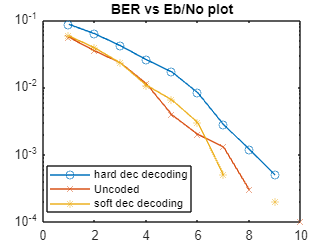


semilogy(Eb_Nodb,BER_hardcode,'o-','DisplayName','hard dec decoding');
legend('Location',"best");
hold on
semilogy(Eb_Nodb,BER_uncoded,'x-','DisplayName','Uncoded');
semilogy(Eb_Nodb,BER_softcode, '*-',"DisplayName",'soft dec decoding');
hold off
title ("BER vs Eb/No plot");